# Aliasing

An illustration of aliasing due to undersampling.

In this example, we sample a cosine waveform with frequency $\omega_0$ = 10 rad/s at a sampling rate $\omega_s = 1.5\omega_0$. That is less than the minimum $\omega_s = 2\omega_0$.

Prepared for EG-247 Signals and Systems by Dr Chris Jobling.

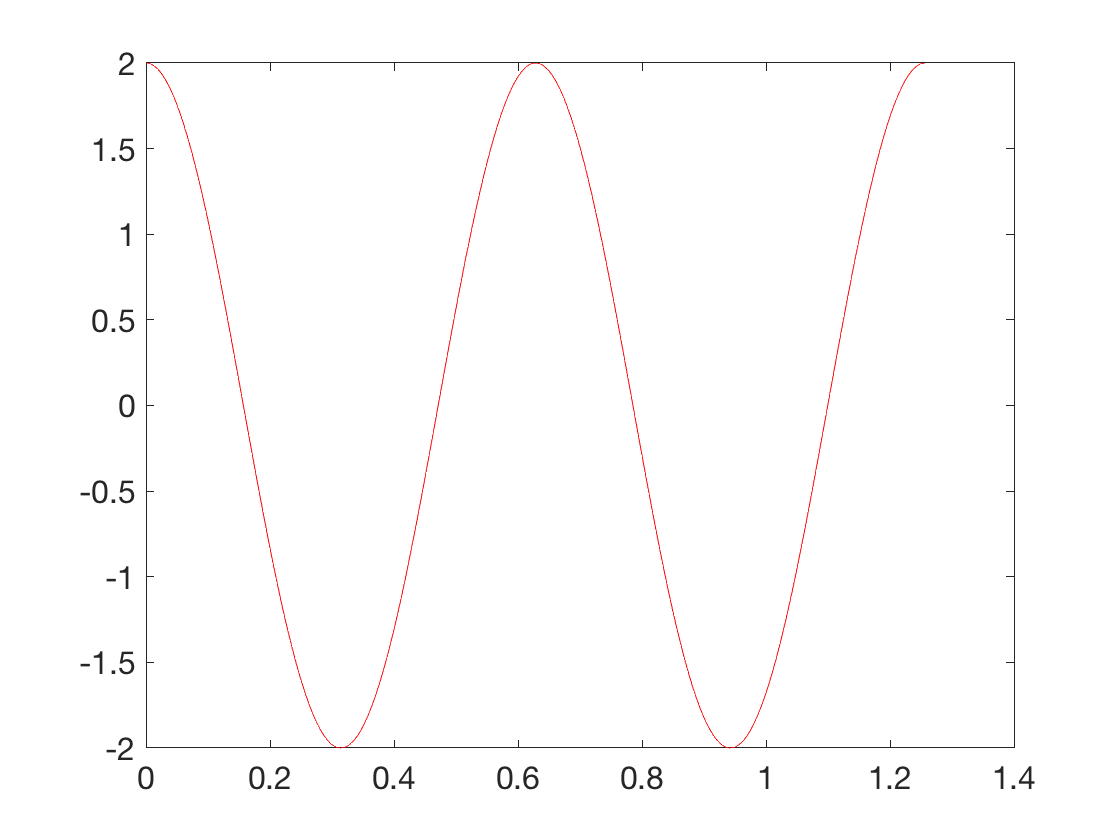

A = 2;
w0 = 10;
ws = 1.5*w0;
Ts = 2*pi/ws;
tmax = 2*(2*pi/w0);
t = linspace(0,tmax,1000);
plot(t,A*cos(w0*t),'r')
hold on

## Now we sample

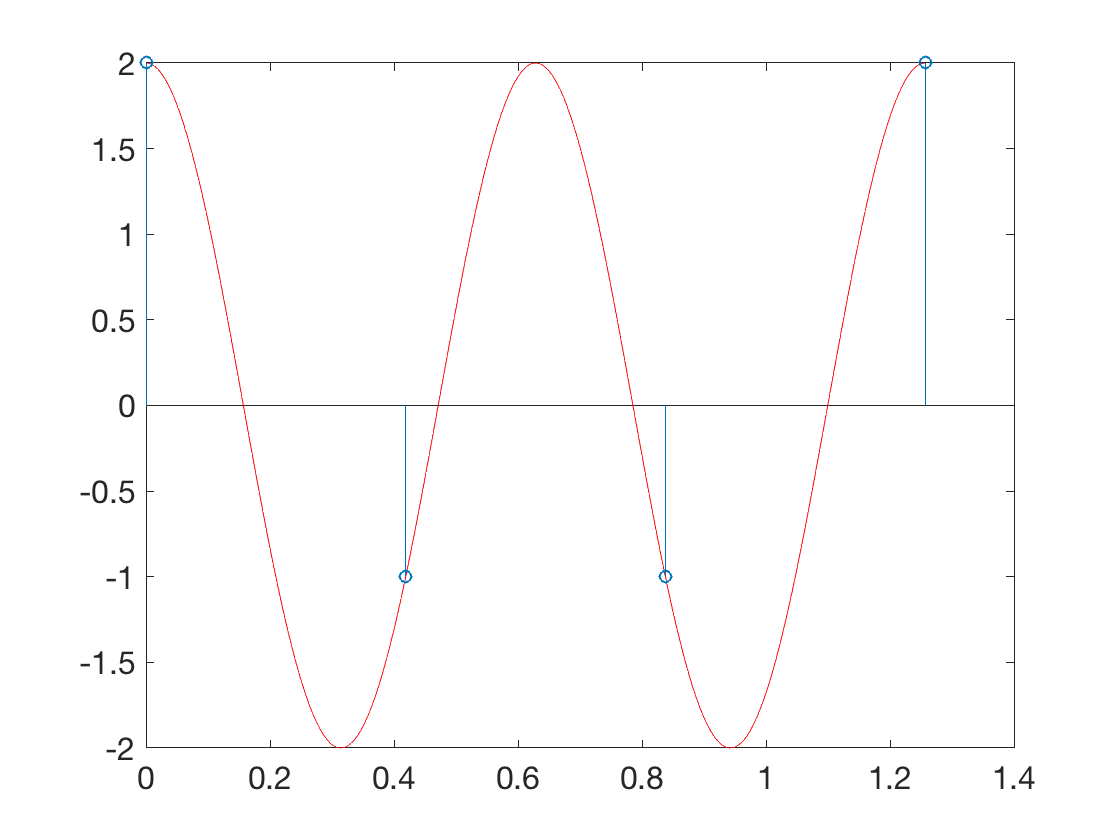

ts = 0:Ts:tmax;
stem(ts,A*cos(w0*ts))

we observe that a waveform with half the frequency of the original would have the same sampled points.

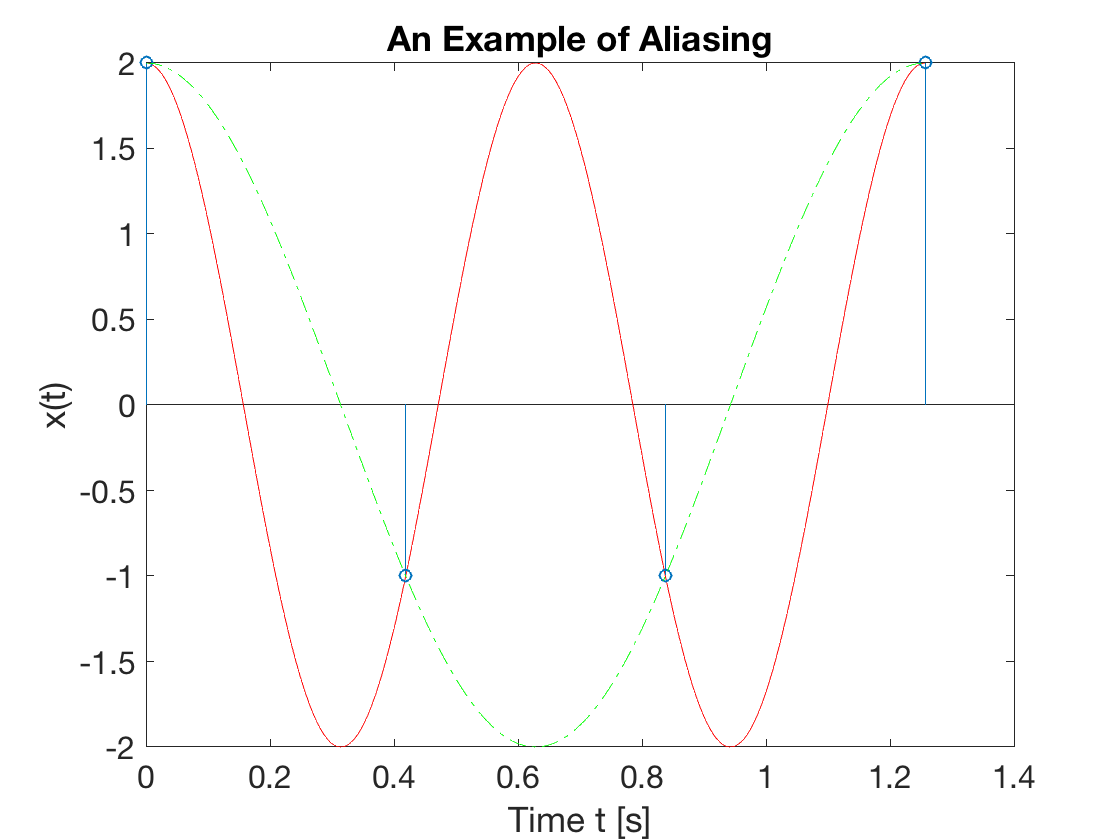

plot(t,A*cos(w0*t/2),'g-.')
hold off
title('An Example of Aliasing')
xlabel('Time t [s]')
ylabel('x(t)')